# Aplicaciones de la derivada: máximos, mínimos y puntos de inflexión

Procedimiento para obtener los extremos relativos (o absolutos) de una función $f(x)$:

**Paso 1. **Hallar el dominio de $f(x)$.

**Paso 2. **Estudio de los puntos donde la función no es continua, ya que en ellos tampoco será derivable.

**Paso 3. **Cálculo de los puntos críticos. Resolviendo $f'(x)=0$ se obtienen los posibles extremos relativos de $f(x)$.

**Paso 4. **Clasificación de los puntos críticos como máximo o mínimo relativo utilizando el criterio de la segunda derivada.

**Paso 5.** En el caso en que el dominio de $f(x)$, sea un intervalo cerrado $[a,b]$, se procede:

- Hallar la imagen de $f$ en $a$, $b$, y en cualquier punto $c$, que haya anulado $f'(x)$.

- Comparar los valores de $f$ anteriores para hallar donde la función alcanza el mayor valor (máximo absoluto) o el menor valor (mínimo absoluto).

## Ejemplo:

## Determina los intervalos de crecimiento/decrecimiento y los puntos críticos (máximos, mínimos y puntos de inflexión) de la función:


$$f\left(x\right)=\frac{x^2 }{x-1}$$


Analicemos cuál es su dominio. Para ello, busquemos si existe algún punto que anule el denominador:

syms x
solve(x-1==0,x)

$$ans = 1$$

Concluimos que la función no está definida para $x=1$: $Dom(f)=\mathbb{R}-\{1\}$.

Si representamos la función:

syms x
f=x^2/(x-1)

$$f = \frac{x^{2}}{x-1}$$

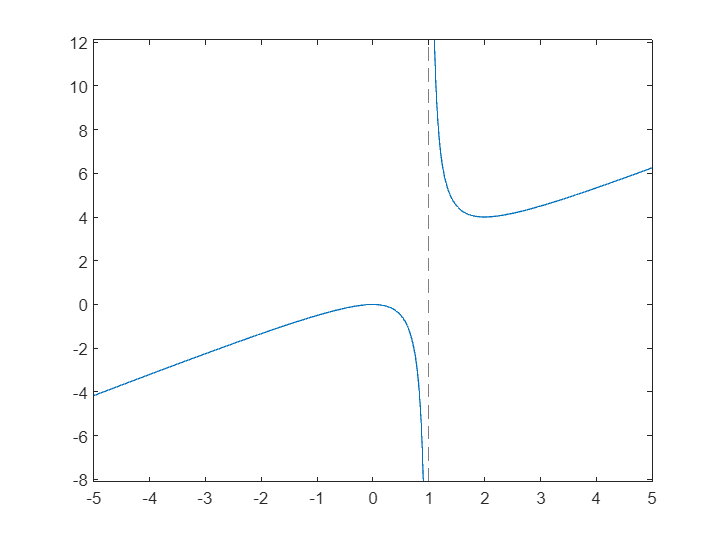

fplot(f)

A partir de la gráfica, se observa que la función no es continua en $x=1$. También podemos deducir que existe un máximo y un mínimo relativos y que la función tiene diversos intervalos de crecimiento y decrecimiento.

A continuación calcularemos analíticamente esta información utilizando las derivadas de la función.

## Monotonía de la función

Calculo $f'(x)$ y guardo el resultado en la variable `der1`:

der1(x)=diff(f,x,1)

$$der1(x) = \frac{2\,x}{x-1}-\frac{x^{2}}{{\left(x-1\right)}^{2}}$$

simplify(der1)

$$ans(x) = \frac{x\,\left(x-2\right)}{{\left(x-1\right)}^{2}}$$

Anulo la primera derivada:

p_crit=solve(der1==0,x)

$$p\_crit = \left(\begin{array}{c} 0\\ 2 \end{array}\right)$$

En estos dos puntos se produce un cambio en el signo de la derivada. Por tanto, la función pasará de ser creciente a decreciente o viceversa. Analicemos qué sucede con el signo de $f'(x)$ alrededor de $x=0$ y $x=2$:

(Recordemos que el punto $x=1$ no está en el dominio de $f$)

der1(-0.5)

$$ans = \frac{5}{9}$$

der1(0.5)

$$ans = -3$$

der1(1.5)

$$ans = -3$$

der1(3)

$$ans = \frac{3}{4}$$

Con la información anterior podemos deducir que:

- $f$ es creciente en $(-\infty, 0)\cup(2,+\infty)$

- $f$ es decreciente en $(0,1)\cup (1,2)$

## Clasificación de los puntos críticos

Habíamos obtenido 2 puntos críticos:

pc1=0;
pc2=2;

Para clasificarlos, guardo en `der2` la segunda derivada $f''(x)$:

der2(x)=diff(f,x,2)

$$der2(x) = \frac{2}{x-1}-\frac{4\,x}{{\left(x-1\right)}^{2}}+\frac{2\,x^{2}}{{\left(x-1\right)}^{3}}$$

simplify(der2)

$$ans(x) = \frac{2}{{\left(x-1\right)}^{3}}$$

Clasifico los puntos críticos utilizando el criterio de la segunda derivada:

der2(0)

$$ans = -2$$

Como $f''(0)<0$, en $x=0$ la función tiene un máximo relativo.

der2(2)

$$ans = 2$$

Como $f''(2)>0$, en $x=2$ la función tiene un mínimo relativo.

## Puntos de inflexión

Pasamos a calcular en qué punto se anula la segunda derivada:

solve(der2==0,x)

 
ans =
 
Empty sym: 0-by-1
 


Esta función no tiene puntos de inflexión porque no hay puntos donde se anule la segunda derivada.

En caso de tenerlos, los puntos de inflexión son aquellos puntos en los que la función pasa de ser cóncava a convexa, o vicecersa. Podríamos utilizar el siguiente criterio para determinar la curvatura de la función:

*Sea *$y=f(x)$* una función dos veces derivable en *$]a,b[$*. Entonces:*

- *Si *$f''(x)\geq 0$* para todo *$x\in]a,b[$*, entonces *$f$*es ****cóncava**** en *$]a,b[$*.*

- *Si *$f''(x)\leq 0$* para todo *$x\in]a,b[$*, entonces *$f$*es ****convexa**** en *$]a,b[$*.*

# Ejercicios propuestos

## Actividad 1. 

Calcula y clasifica los puntos críticos de $f(x)=x^3(x-2)^2$.

syms x
f=(x^3)*((x-2)^2)

$$f = x^{3}\,{\left(x-2\right)}^{2}$$

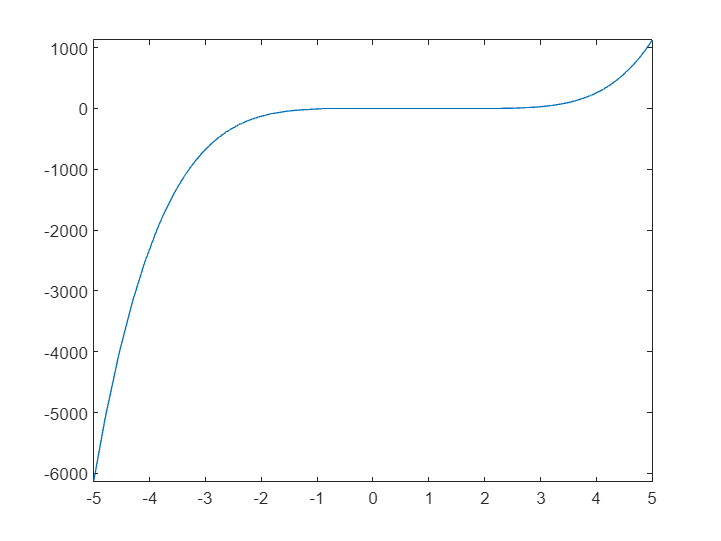

fplot(f)

dir1(x)=diff(f,x,1)

$$dir1(x) = x^{3}\,\left(2\,x-4\right)+3\,x^{2}\,{\left(x-2\right)}^{2}$$

simplify(dir1)

$$ans(x) = x^{2}\,\left(5\,x^{2}-16\,x+12\right)$$

crit=solve(dir1==0,x)

$$crit = \left(\begin{array}{c} 0\\ 0\\ \frac{6}{5}\\ 2 \end{array}\right)$$

pt1=0;
pt2=6/5;
pt3=2;
dir2(x)=diff(f,x,2)

$$dir2(x) = 6\,x\,{\left(x-2\right)}^{2}+6\,x^{2}\,\left(2\,x-4\right)+2\,x^{3}$$

simplify(dir2)

$$ans(x) = 4\,x\,\left(5\,x^{2}-12\,x+6\right)$$

dir2(0)

$$ans = 0$$

dir2(6/5)

$$ans = -\frac{144}{25}$$

dir2(2)

$$ans = 16$$

## Actividad 2. 

Realiza un estudio de la siguiente función: 


$$f\left(x\right)=x^3$$


determinando los puntos de corte con los ejes, máximos y mínimos relativos, y puntos de inflexión.

syms x
g=x^3

$$g = x^{3}$$

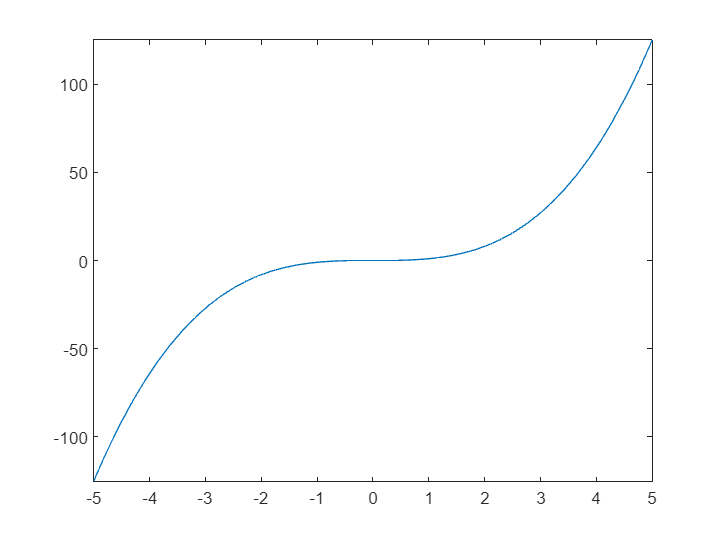

fplot(g)

solve(g==0)

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

solve(g,x==0)

$$ans = 0$$

dig1(x)=diff(g,x,1)

$$dig1(x) = 3\,x^{2}$$

dig2(x)=diff(g,x,2)

$$dig2(x) = 6\,x$$

pcrit=solve(dig1==0,x)

$$pcrit = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

dig2(0)

$$ans = 0$$

pinf=solve(dig2==0,x)

$$pinf = 0$$

## Actividad 3. 

Representa la función$f(x)=\frac{2x+1}{x^2-1}$ y calcula sus intervalos de crecimiento y decrecimiento.

syms x
h=(2*x+1)/((x^2)-1)

$$h = \frac{2\,x+1}{x^{2}-1}$$

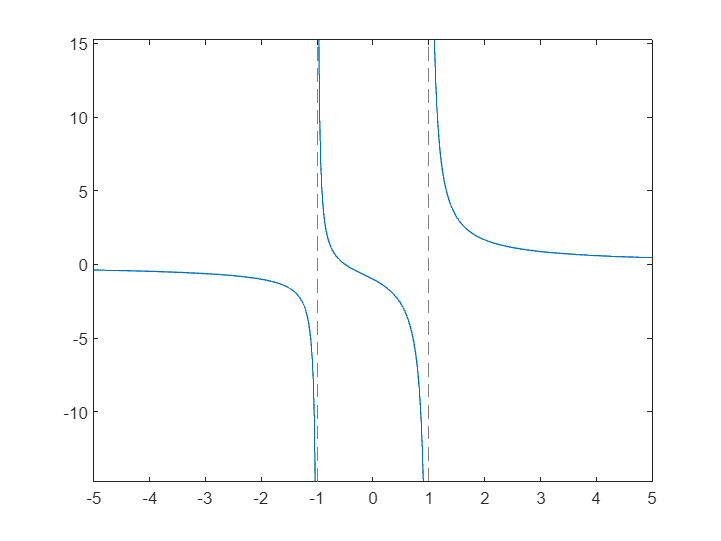

fplot(h)

dih1(x)=diff(h,x,1)

$$dih1(x) = \frac{2}{x^{2}-1}-\frac{2\,x\,\left(2\,x+1\right)}{{\left(x^{2}-1\right)}^{2}}$$

simplify(dih1)

$$ans(x) = -\frac{2\,\left(x^{2}+x+1\right)}{{\left(x^{2}-1\right)}^{2}}$$

hcrit=solve(dih1==0,x)

$$hcrit = \left(\begin{array}{c} -\frac{1}{2}-\frac{\sqrt{3}\,\mathrm{i}}{2}\\ -\frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2} \end{array}\right)$$

dih1(-3)

$$ans = -\frac{7}{32}$$

dih1(0)

$$ans = -2$$

dih1(3)

$$ans = -\frac{13}{32}$$

## Actividad 4. 

Calcula los extremos relativos y los intervalos de crecimiento y decrecimiento de $f(x)=-\frac{x^2}{x^2+1}$ en $[-3,3]$.

syms x
j=-(x^2)/((x^2)+1)

$$j = -\frac{x^{2}}{x^{2}+1}$$

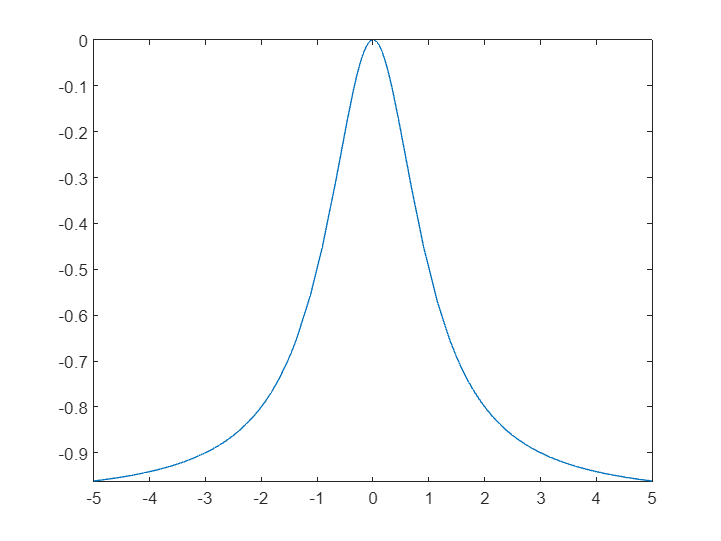

fplot(j)

dij1(x)=diff(j,x,1)

$$dij1(x) = \frac{2\,x^{3}}{{\left(x^{2}+1\right)}^{2}}-\frac{2\,x}{x^{2}+1}$$

ext_rel_j=solve(dij1==0,x)

$$ext\_rel\_j = 0$$

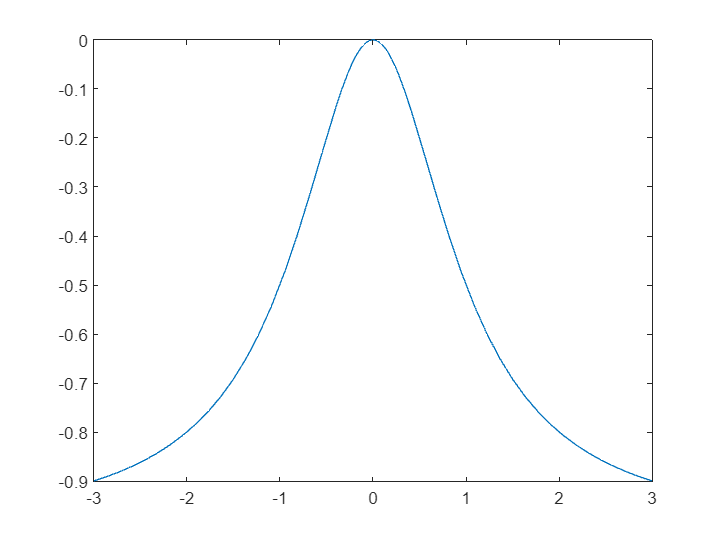

fplot(j,[-3,3])

dij1(-3)

$$ans = \frac{3}{50}$$

dij1(0)

$$ans = 0$$

dij1(3)

$$ans = -\frac{3}{50}$$

## Actividad 5. 

Dada la curva $f(x)=ax^3+bx^2+cx$, encuentra el valor de los parámetros $a,b,c\in\mathbb{R}$ para que $f$ tenga un punto de inflexión en $(1,2)$ y además la pendiente de la recta tangente en ese mismo punto sea $-2$.

syms x
syms a
syms b
syms c

k=(a*x^3)+(b*x^2)+c*x

$$k = a\,x^{3}+b\,x^{2}+c\,x$$

dik1(x)=diff(k,x,1)

$$dik1(x) = 3\,a\,x^{2}+2\,b\,x+c$$

dik2(x)=diff(k,x,2)

$$dik2(x) = 2\,b+6\,a\,x$$

y=2
b=solve(b==y/-2)

$$b = -1$$

x=1

x = 1

y = 2

a=solve(a==(4*x)/(6*x))

$$a = \frac{2}{3}$$

c=solve(c==(-3*a*x^2)+(-2*b*x)+y)

$$c = 2$$